if ~exist('binary_map','var')
    define_binary_map;
end

N_pts = 100

N_pts = 100

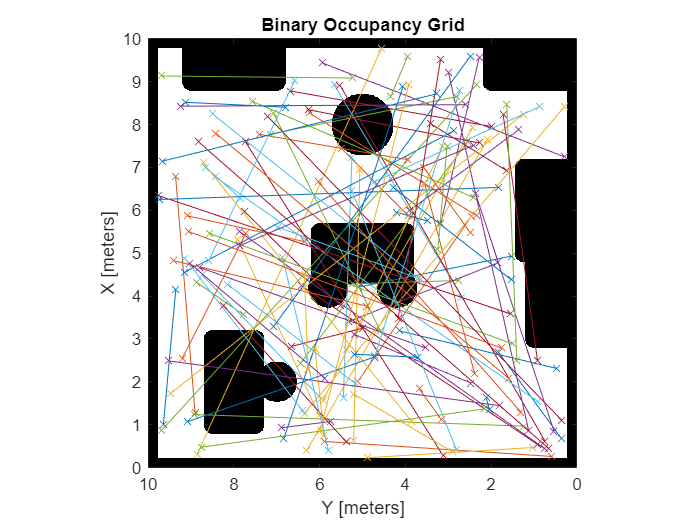


start_pts = NaN([N_pts 2]);
end_pts = NaN([N_pts 2]);
for i = 1:N_pts
    start_pts(i,:) = rand_pt_in_map(binary_map_inflated);
    end_pts(i,:) = rand_pt_in_map(binary_map_inflated);
end

show(binary_map_inflated);
hold on
for i = 1:N_pts
    plot([start_pts(i,1) end_pts(i,1)], [start_pts(i,2) end_pts(i,2)], '-x')
end
hold off

view(-90,90);


line_lens = vecnorm(start_pts'-end_pts')';

Set up planners

% Bug
N_planner_steps = 1e3

N_planner_steps = 1000

T = 0.1; % Sampling period
lidar = rangeSensor("Range",[0 1], "HorizontalAngleResolution", 2*pi/90);

bug = ctrl_bug();
bug.v_max = 1;
bug.T = T;
bug.angle_eps = 2*pi/90;
bug.min_obstacle_dist = 0.20;

bug_paths = cell(N_pts,1);
bug_lens = NaN(N_pts,1);
bug_success = NaN(N_pts,1);

% Potential Field

poten_paths = cell(N_pts,1);
poten_times = NaN(N_pts,1);
poten_lens = NaN(N_pts,1);
poten_success = NaN(N_pts,1);

poten = ctrl_potential();
poten.v_max = 1;
poten.k_goal = 10;
poten.avoidance_strength = 0.1;
poten.avoidance_distance = 0.1;
poten.robot_radius = 0.2;

% PRM
prm = mobileRobotPRM(binary_map_inflated);

prm_paths = cell(N_pts,1);
prm_times = NaN(N_pts,1);
prm_lens = NaN(N_pts,1);
prm_success = NaN(N_pts,1);

% RRT
ss = stateSpaceSE2;
sv = validatorOccupancyMap(ss);
sv.Map = binary_map_inflated;
sv.ValidationDistance = 0.01;
ss.StateBounds = [binary_map_inflated.XWorldLimits;binary_map_inflated.YWorldLimits; [-pi pi]];
planner = plannerRRT(ss,sv);
planner.MaxConnectionDistance = 0.3;

[pthObj,solnInfo] = plan(planner,[start_pts(1,:) 0],[end_pts(1,:) 0]);

rrt_paths = cell(N_pts,1);
rrt_times = NaN(N_pts,1);
rrt_lens = NaN(N_pts,1);
rrt_success = NaN(N_pts,1);

Loop over all the start/end points

for i = 1:N_pts
disp(i)

% Bug
bug_paths{i} = NaN(N_planner_steps, 2);
robot_state = start_pts(i,:);
for k = 1:N_planner_steps
    bug_paths{i}(k,:) = robot_state;

    [ranges,angles] = lidar([robot_state 0],binary_map);
    v_xy = bug.step(robot_state, end_pts(i,:), ranges, angles);

    robot_state = robot_state + v_xy * T;

    bug_success(i) = norm(robot_state - end_pts(i,:)) < 1e-2;
    if bug_success(i)
        bug_paths{i}(k+1,:) = robot_state;
        break
    end
end
bug_lens(i) = sum(vecnorm(diff(bug_paths{i})'), 'omitnan');

% Potential Field
poten_paths{i} = NaN(N_planner_steps, 2);
robot_state = start_pts(i,:);
for k = 1:N_planner_steps
    poten_paths{i}(k,:) = robot_state;

    [ranges,angles] = lidar([robot_state 0],binary_map);
    v_xy = poten.step(robot_state, end_pts(i,:), ranges, angles);

    robot_state = robot_state + v_xy * T;

    poten_success(i) = norm(robot_state - end_pts(i,:)) < 1e-2;
    if poten_success(i)
        poten_paths{i}(k+1,:) = robot_state;
        break
    end
end
poten_lens(i) = sum(vecnorm(diff(poten_paths{i})'), 'omitnan');

% PRM
tic
prm = mobileRobotPRM(binary_map_inflated); % make new graph
xy = findpath(prm,start_pts(i,:),end_pts(i,:));
prm_times(i) = toc;
prm_paths{i} = xy;
prm_lens(i) = sum(vecnorm(diff(xy)'), 'omitnan');
prm_success(i) = norm(prm_paths{i}(end,:)- end_pts(i,:)) < 1e-2;

% RRT
tic
[pthObj,solnInfo] = plan(planner,[start_pts(i,:) 0],[end_pts(i,:) 0]);
rrt_times(i) = toc;
xy = pthObj.States(:,1:2);
rrt_paths{i} = xy;
rrt_lens(i) = sum(vecnorm(diff(xy)'), 'omitnan');
rrt_success(i) = solnInfo.IsPathFound == 1;


end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100



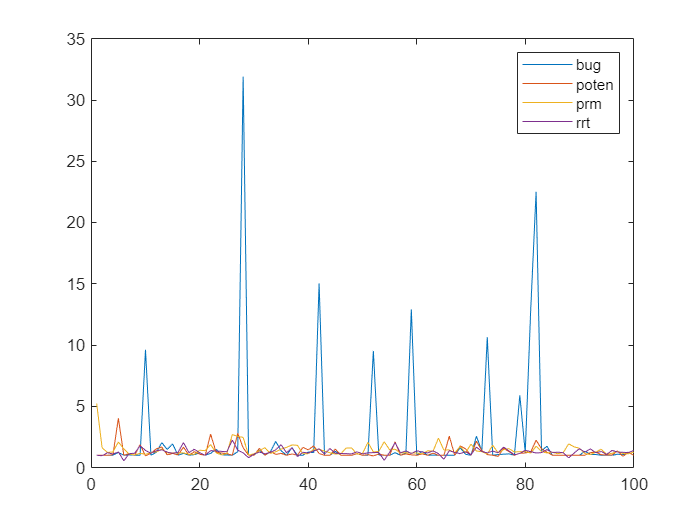

plot(bug_lens./line_lens); hold on
plot(poten_lens./line_lens)
plot(prm_lens./line_lens)
plot(rrt_lens./line_lens); hold off
legend(["bug", "poten", "prm", "rrt"])

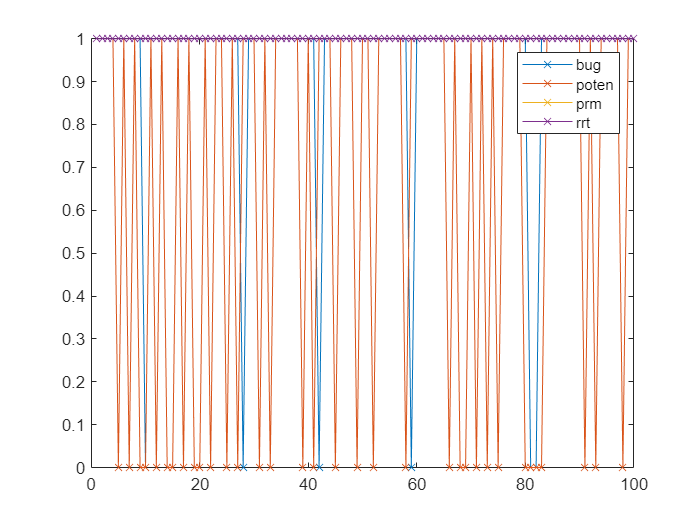


plot(bug_success, '-x'); hold on
plot(poten_success, '-x')
plot(prm_success, '-x')
plot(rrt_success, '-x'); hold off
legend(["bug", "poten", "prm", "rrt"])

i = 2

i = 2

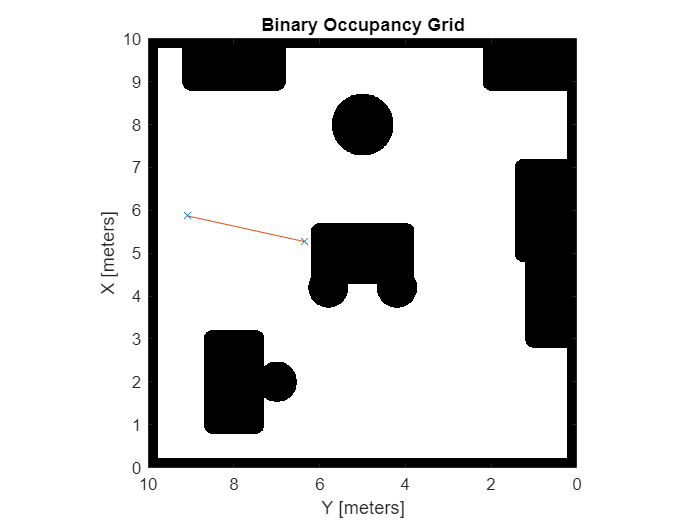


show(binary_map_inflated);
hold on

plot([start_pts(i,1) end_pts(i,1)], [start_pts(i,2) end_pts(i,2)], '-x')
plot(poten_paths{i}(:,1),poten_paths{i}(:,2))

hold off

view(-90,90);

% Plots for local motion planning
sum(bug_success)/N_pts

ans = 0.9200

sum(poten_success)/N_pts

ans = 0.7900

histogram(bug_lens(bug_success==1), -1:30); hold on
histogram(poten_lens(poten_success==1), -1:30); hold off

xline(mean(bug_lens(bug_success==1)), 'r')
xline(mean(poten_lens(poten_success==1)), 'b')
hold off
ylabel("# Occurrences")
xlabel("Path Length (m)")
legend("Bug", "Poten", 'Location','best')
mean(bug_lens(bug_success==1))

ans = 6.1810

mean(poten_lens(poten_success==1))

ans = 6.2429

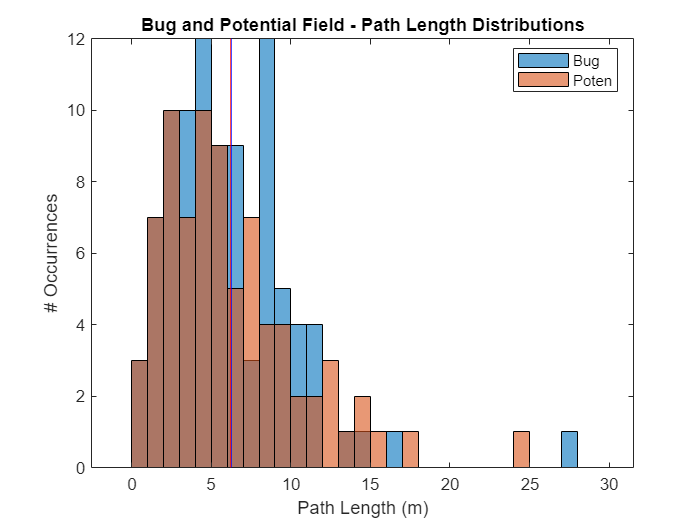

title("Bug and Potential Field - Path Length Distributions")


i = 49

i = 49

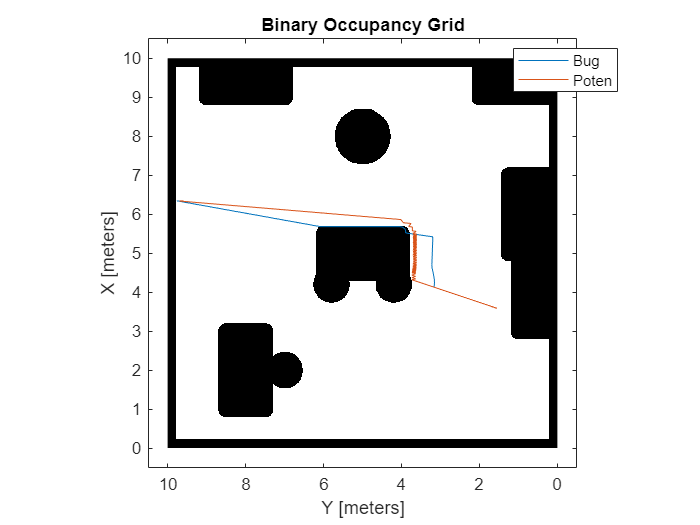


show(binary_map_inflated);
hold on


plot(bug_paths{i}(:,1),bug_paths{i}(:,2))
plot(poten_paths{i}(:,1),poten_paths{i}(:,2))
%plot([start_pts(i,1) end_pts(i,1)], [start_pts(i,2) end_pts(i,2)], '-x')

hold off
legend("Bug", "Poten", 'Location','best')

view(-90,90);

% Plots for global motion planning

plot(prm_times, prm_lens, 'x'); hold on
plot(rrt_times, rrt_lens, 'x');
xline(mean(prm_times), 'b')
xline(mean(rrt_times), 'r')
yline(mean(prm_lens), 'b')
yline(mean(rrt_lens), 'r')
hold off
xlabel("Computation Time (sec)")
ylabel("Path Length (m)")
legend("PRM", "RRT", 'Location','best')
mean(prm_times)

ans = 0.1021

mean(rrt_times)

ans = 0.0301

mean(prm_lens)

ans = 6.9520

mean(rrt_lens)

ans = 6.7469

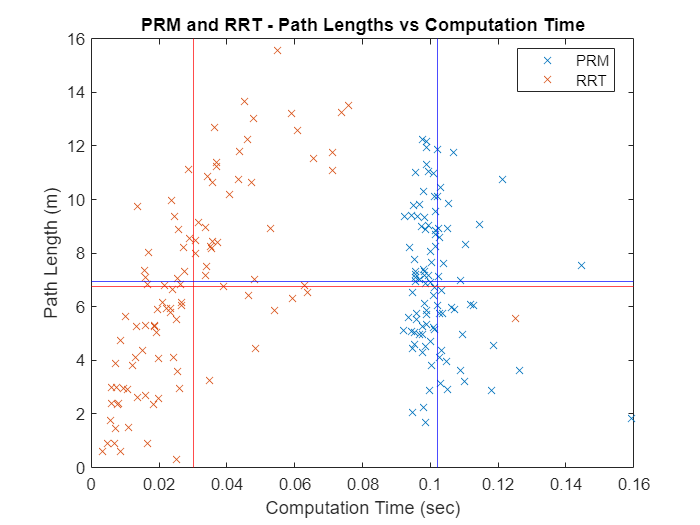

title("PRM and RRT - Path Lengths vs Computation Time")


i = 49

i = 49

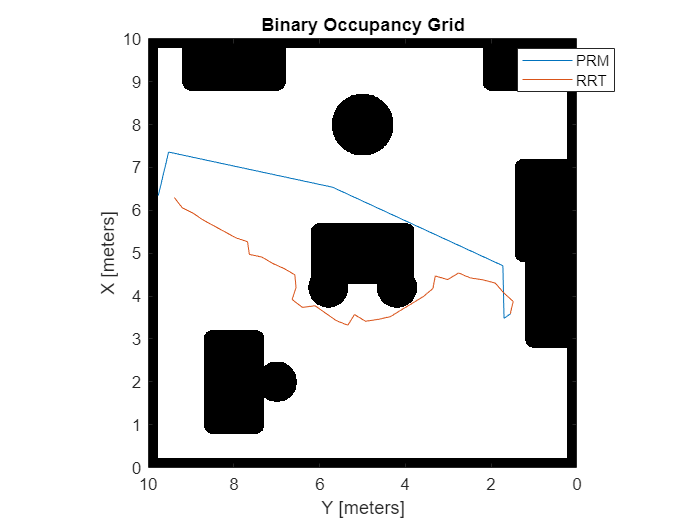


show(binary_map_inflated);
hold on


plot(prm_paths{i}(:,1),prm_paths{i}(:,2))
plot(rrt_paths{i}(:,1),rrt_paths{i}(:,2))
%plot([start_pts(i,1) end_pts(i,1)], [start_pts(i,2) end_pts(i,2)], '-x')

hold off
legend("PRM", "RRT", 'Location','best')

view(-90,90);